edge_list = [1 2;
             1 3;
             2 4;
             3 4;
             4 5];

G = digraph(edge_list(:,1), edge_list(:,2));

nodeLabels = {'A' , 'B' , 'C' , 'D' , 'E'}

nodeLabels = 1×5 cell array
    {'A'}    {'B'}    {'C'}    {'D'}    {'E'}


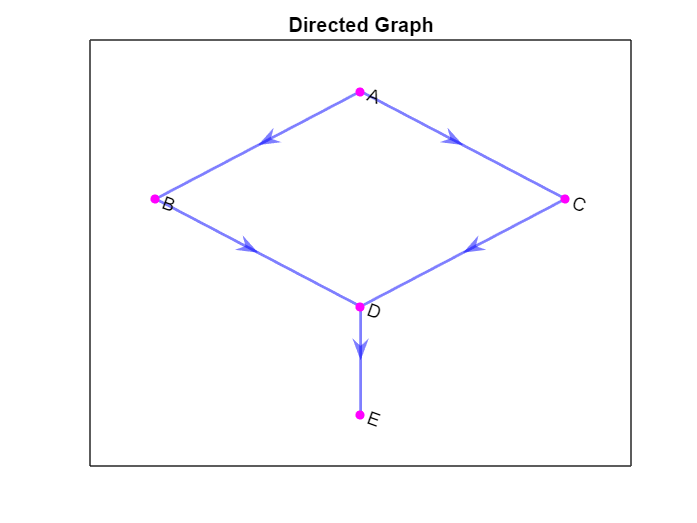


figure;
plot(G, 'Layout', 'layered' , 'NodeLabel', nodeLabels, ...
    'EdgeColor' , 'blue' , 'ArrowSize' , 12, ...
    'LineWidth',1.5,'NodeColor','magenta');
title('Directed Graph');


[starNode, endNode] = deal(1 , 5);
[path, totalDistance] = shortestpath(G, starNode , endNode);

fprintf('Shortest path from %s to %s:\n' , nodeLabels{starNode} , nodeLabels{endNode});

Unrecognized function or variable 'startNode'.

disp(nodeLabels(path));
fprintf('Total steps: %d\n' , totalDistance);